%% Script to get reduced brightness image using JND_pixel.m using lab colour space
clear; 
img_list = ["input/fruit.jpg";"input/library.jpg";"input/ubc.jpg"];
%img_list = ["input/fruit.jpg"];

for idx = 1:numel(img_list)

% Hyperparameters
Reduce_factor = 0.6;
Enhance_factor = 3.0;
tolerance = 0.01;
TUNING_FACTOR = 0.005; % should be smaller than tolerance 

% FIXED PARAMETERS
HF_MULTIPLIER = 1; % starting multiplier for brightness reduction: range [1,2]
LF_MULTIPLIER = 1; % starting multiplier for brightness reduction: range (0,1]

% Original images
Orig_img = imread(img_list(idx));

% Dim the original image
Dim_img = dim_image(Orig_img, Reduce_factor);
[path,input_filename, ext] = fileparts(img_list(idx));
dimmed_file = "tmp/" + input_filename + "_dimmed" + ext;
imwrite(Dim_img, dimmed_file, 'jpg');

% Enhance the dimmed image with CSF method
enhanced_file = "tmp/" + input_filename + "_enhanced" + ext;
system("java Contrast " + dimmed_file + " " + enhanced_file + " " + Enhance_factor);
enhance_img = imread(enhanced_file);


Reading input file.
Dimensions3 1067 1600
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 497
Number of hillocks is 5
 Number of components is 6
Number of hillocks is 9
 Number of components is 1
Number of hillocks is 9
 Number of components is 0
Number of hillocks is 8
 Number of components is 1
Number of hillocks is 8
 Number of components is 0
Number of hillocks is 7
 Number of components is 0
Number of hillocks is 6
 Number of components is 0
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 Number of components is 1
Number of hillocks is 5
 N

Reading input file.
Dimensions3 529 700
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 280
Number of hillocks is 1
 Number of components is 736
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 1
Number of hillocks is 17
 Number of components is 0
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hi

Reading input file.
Dimensions3 651 970
Converted the Image to Lxy notation
Generated the Maximum Envelop
Starting first pass.
 Number of components is 1
Number of hillocks is 1
 Number of components is 146
Number of hillocks is 1
 Number of components is 496
Number of hillocks is 13
 Number of components is 5
Number of hillocks is 15
 Number of components is 2
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 1
Number of hillocks is 16
 Number of components is 0
Number of hillocks is 15
 Number of components is 1
Number of hillocks is 15
 Number of components is 1
Number of hillocks is 15
 Number of components is 0
Number of hi

Original brightness: 37.2808


Dimmed brightness: 22.0186


Enhanced brightness: 30.7178


Original JND Values: min 4.9964 max 20.35


Final JND Values: min 0 max 19.7395


Reduced brightness: 22.0277


Original brightness: 31.6675


Dimmed brightness: 18.5509


Enhanced brightness: 29.045


Original JND Values: min 5.4869 max 19.2253


Final JND Values: min 0 max 22.6406


Reduced brightness: 18.5602


Original brightness: 58.4983


Dimmed brightness: 35.9788


Enhanced brightness: 52.2044


Original JND Values: min 5.3535 max 18.8075


Final JND Values: min 7.4733 max 39.5558


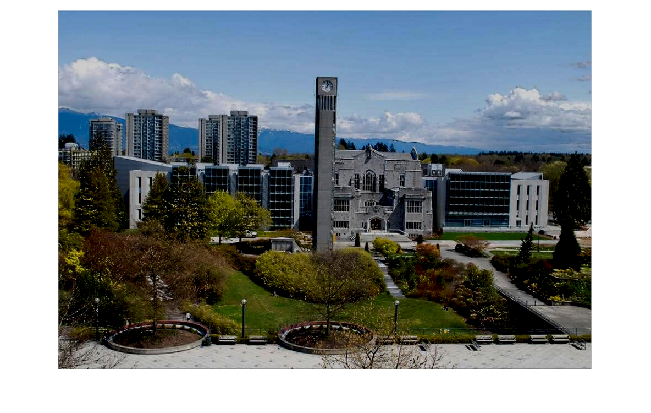

Reduced brightness: 35.9818



I = enhance_img;

% Get high frequency multiplier matrix
y = get_HF_multiplier(I, HF_MULTIPLIER);
x = get_LF_multiplier(I, LF_MULTIPLIER);

% Convert to lab colour space using rgb2lab
lab_im = rgb2lab(I);
lab_y_im = lab_im(:,:,1);

% Calculate brightness reduction target 
dim_y = calc_lab_brightness(Dim_img);
enhance_y = calc_lab_brightness(enhance_img);
brightness_change = enhance_y - dim_y;

% Reduce JND
% Run JND_pixel 
JND_im = JND_pixel(lab_y_im, 'Yang');
% Calculate JND average brightness change
mean_JND = mean(JND_im(:));
% Apply high frequency multiplier matrix
mult_JND_im = times(JND_im, y);
mean_HF_JND = mean(mult_JND_im(:));

% Check how far away we are from target
target_diff = dim_y - mean2(lab_y_im - mult_JND_im);

new_multiplier = 1;
if target_diff > abs(tolerance)
    % Increase the brightness of the image through smaller JND values
    % Multiply JND values by LF multiplier < 1 until we get 0 target_diff
    i = 0;
    while abs(target_diff) > abs(tolerance)
        if abs(target_diff) > abs(0.5) && i < 10
            % Coarse tuning
            tuning_factor = 0.25;
        else
            % Fine tuning
            tuning_factor = TUNING_FACTOR;
        end

        if target_diff > abs(tolerance)
        % Brightness needs to be increased 
            new_multiplier = new_multiplier - tuning_factor;
        else 
        % Brightness needs to be reduced 
            new_multiplier = new_multiplier + tuning_factor;
        end

        % Apply multiplier to JND values 
        x = get_LF_multiplier(I, new_multiplier);

        % Apply low frequency multiplier matrix
        mult_JND_im = times(JND_im, x);

        % Check how far away we are from target
        target_diff = dim_y - mean2(lab_y_im - mult_JND_im);
        i = i+1;
    end
elseif target_diff < -tolerance
    % Tuning of HF multiplier to reduce image brightness
    i = 0; % number of iterations
    while abs(target_diff) > abs(tolerance)
        j = 1; % scaling factor
        if abs(target_diff) > abs(0.5) && i < 10
            % Coarse tuning
            tuning_factor = 0.25;
        else
            % Fine tuning
            tuning_factor = TUNING_FACTOR;
        end

        if target_diff > abs(tolerance)
            % Brightness needs to be increased 
            new_multiplier = new_multiplier - tuning_factor;
        else 
            % Brightness needs to be reduced 
            new_multiplier = max(new_multiplier + tuning_factor,1);
        end
    
        % Get high frequency multiplier matrix
        y = get_HF_multiplier(I, new_multiplier);

        % Apply high frequency multiplier matrix
        mult_JND_im = times(JND_im, y);

        % Check how far away we are from target
        target_diff = dim_y - mean2(lab_y_im - mult_JND_im);
        i = i+1;
    end
else 
    % No changes needed to JND values
    mult_JND_im = JND_im
end

% Reduce brightness of luminance image by JND values
new_im = lab_y_im - mult_JND_im;

% Update modified L channel
lab_im(:,:,1) = new_im;

% Convert back to rgb 
rgb_im = lab2rgb(lab_im);

% Calculate brightness change
orig_y = calc_lab_brightness(Orig_img);
new_y = calc_lab_brightness(rgb_im);

% Display the original image
imshow(Orig_img);
disp(['Original brightness: ' num2str(orig_y)]);

% Display the dimmed image
imshow(Dim_img);
disp(['Dimmed brightness: ' num2str(dim_y)]);

% Display the enhanced image
imshow(enhance_img);
disp(['Enhanced brightness: ' num2str(enhance_y)]);

% Display original JND matrix
imshow(uint8(rescale(JND_im, 0, 255)));
[minB, maxB] = bounds(JND_im,"all");
disp(['Original JND Values: min ' num2str(minB) ' max ' num2str(maxB)]);

% Display the final JND matrix
imshow(uint8(rescale(mult_JND_im, 0, 255)));
[minA, maxA] = bounds(mult_JND_im,"all");
disp(['Final JND Values: min ' num2str(minA) ' max ' num2str(maxA)]);

% Display the brightness-reduced image
imshow(rgb_im);
disp(['Reduced brightness: ' num2str(new_y)]);

% Save the images to an output directory
imwrite(Orig_img, 'output/' + input_filename + '_' + num2str(orig_y) + '_input.jpg', 'jpg');
imwrite(Dim_img, 'output/' + input_filename + '_' + num2str(dim_y) + '_dimmed.jpg', 'jpg');
imwrite(enhance_img, 'output/' + input_filename + '_' + num2str(enhance_y) + '_enhanced.jpg', 'jpg');
imwrite(rgb_im, 'output/' + input_filename + '_' + num2str(new_y) + '_output.jpg', 'jpg');
imwrite(uint8(rescale(mult_JND_im, 0, 255)), 'output/' + input_filename + '_' + num2str(minA) + '_' + num2str(maxA) + '_finalJND.jpg', 'jpg');
imwrite(uint8(rescale(JND_im, 0, 255)), 'output/' + input_filename + '_' + num2str(minB) + '_' + num2str(maxB) + '_origJND.jpg', 'jpg'); 
end

delete('tmp/*'); % Delete intermediate output from Java code
